A1 = @(mu) [
    0 1 mu
    0 0 1
    -1 0 -1
    ];
A2 = @(mu) [
    0 1 0
    0 mu 1
    -1 0 -1
    ];
A3 = @(mu) [
    0 1 0
    0 0 1
    -1 0 -1+mu
    ];
A4 = @(mu) [
    mu 1 mu
    mu mu 1
    -1 0 -1
    ];
A5 = @(mu) [
    mu 1 mu
    mu mu 1
    -1 0 -1+mu
    ];

A = A4;

syms mu lambda real
A_sym = A(mu)

$$A\_sym = \left(\begin{array}{ccc} \mu & 1 & \mu \\ \mu & \mu & 1\\ -1 & 0 & -1 \end{array}\right)$$

Det_A = det(eye(3) - lambda*A(mu))

$$Det\_A = -\lambda^{3}\,\mu +\lambda^{3}+\lambda^{2}\,\mu^{2}-2\,\lambda^{2}\,\mu -2\,\lambda \,\mu +\lambda +1$$

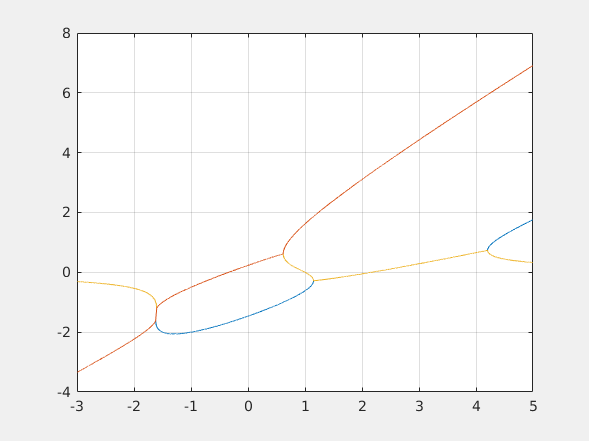

N_mu = 15000;
mu = linspace(-3,5,N_mu);
Eigs = zeros(3,N_mu);
for i = 1:N_mu
    Eigs(:,i) = eig(A(mu(i)));
end
Eigs = switch_Eigs3(Eigs);

fig = figure(12);
fig.Visible = 'on';
Tl = tiledlayout(1,1);
hold on, grid on, box on;
plot3(mu,real(Eigs'),imag(Eigs'))

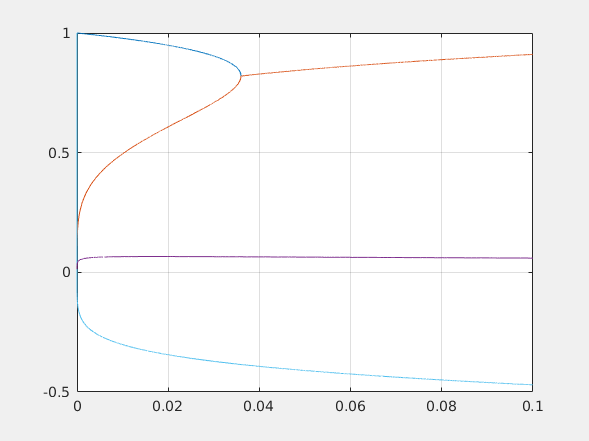

%          6  5 4 3 2 1  0
p = @(mu) [1 -1 0 0 0 mu mu^2+mu];
N_mu = 15000;
mu = linspace(0,0.1,N_mu);
Eigs = zeros(6,N_mu);
for i = 1:N_mu
    Eigs(:,i) = roots(p(mu(i)));
end
Eigs = switch_Eigs(Eigs);

fig = figure(12);
fig.Visible = 'on';
Tl = tiledlayout(1,1);
hold on, grid on, box on;
plot3(mu,real(Eigs'),imag(Eigs'))

function A = A_N(mu,N)
    a = [1-2*mu mu zeros(1,N-2)];
    A = toeplitz(a,a);
    A(1) = 1-mu;
    A(end) = 1-mu;
end

function Eigs = switch_Eigs3(Eigs)
    for i = 1:width(Eigs)-1
        [~,dim1] = min(abs(Eigs(1,i) - Eigs(:,i+1)));
        [~,dim2] = min(abs(Eigs(2,i) - Eigs(:,i+1)));
        [~,dim3] = min(abs(Eigs(3,i) - Eigs(:,i+1)));
        if ( dim1 ~= 1 || dim2 ~= 2 || dim3 ~= 3 ) && all(sort([dim1,dim2,dim3]) == [1,2,3])
            Eigs(:,i+1:end) = Eigs([dim1,dim2,dim3],i+1:end);
        end
    end
end
function Eigs = switch_Eigs(Eigs)
    n = height(Eigs);
    dim = zeros(1,n);
    for i = 1:width(Eigs)-1
        for d = 1:n
            [~,dim(d)] = min(abs(Eigs(d,i) - Eigs(:,i+1)));
        end
        if any(dim ~= 1:n) && all(sort(dim) == 1:n)
            Eigs(:,i+1:end) = Eigs(dim,i+1:end);
        end
    end
end
